This script considers the problem of dual stage disk drive control from an $H_\infty$ perspective and then from a $\mu$-synthesis perspective.  Assume that we have multiplicative input uncertainty for each actuation input (this is a simple but accurate approach - measured Bode plots can be used to generate the uncertainty weights easily.)  Assume the exogenous input is at the output disturbance and the exogenous outputs are the weighted position and the weighted actuation signals.  The generalized plant for $H_\infty$ synthesis for this system is shown below$P = \pmatrix {0&0&0&W_{\Delta_1}&0\cr 0 & 0&0&0&W_{\Delta_2} \cr W_pG_v & W_pG_p  & W_pG_d & W_pG_v & W_pG_p \cr 0&0&0&W_{u_1}&0 \cr 0 & 0&0&0&W_{u_2} \cr -G_v & -G_p &  -G_d& -G_v & -G_p}$

1.)  Build the generalized plant for $H_\infty$ synthesis.  First we'll pull in the model itself

HDDModel_DS_Uncertain;
Gv = VCM.NominalValue;
Gp = PZT.NominalValue;

Now I'll fit multiplicative uncertainty models as we have before.  However, I'll include a different interactive approach to perform the fit (commented sections).  This is somtimes better behaved than *ucover*.  In the end, I decided to manually fit for accuracy and simplicity.

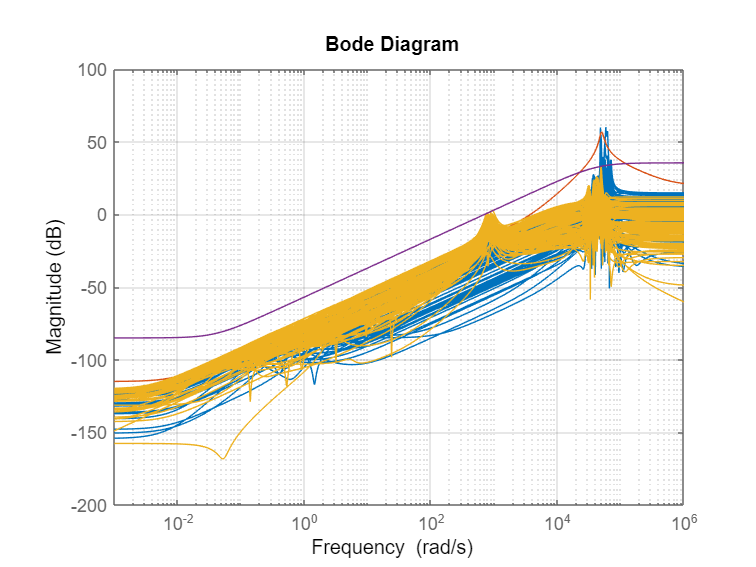

Gp_samples = usample(PZT,100);
%W_D2 = mydrawmag((Gp_samples-Gp)/Gp,2);
% [Pp,info] = ucover(Gp_samples,Gp,4);
% W_D2 = info.W1;
W_D2 = makeweight(10^(-115/20),5000,10)*notch(-40,600000,50000);  %Played with this a bit
Up = ultidyn('Up',[1,1]);
Pp = PZT.NominalValue*(1+W_D2*Up);
Gv_samples = usample(VCM,100);
%W_D1 = mydrawmag((Gv_samples-Gv)/Gv,2);
%[Pv,info] = ucover(Gv_samples,Gv,4);
%W_D1 = info.W1;
W_D1 = makeweight(10^(-85/20),700,60);  %Played with this a bit.
Uv = ultidyn('Uv',[1,1]);
Pv = VCM.NominalValue*(1+W_D1*Uv);
%Check fit
bodemag((Gp_samples-Gp)/Gp,W_D2,(Gv_samples-Gv)/Gv,W_D1,{0.001,1000000});

Now I'll build a performance weight and actuation penalty weights.

Wp = makeweight(100,1000,1/3);  %Simple 1st order weight
Wu_1 = 1/100000;  %Very little weight on VCM - practically unlimited stroke
Wu_2 = makeweight(100,500,1/1000);  %High penalty at low frequency for PZT

For the disturbance model, I'll include a couple of the flexible structure modes of the disk.

Gd = notch(-10,50,800)*notch(-6,100,1100);  %A couple of localized resonances

Now I can build the full generalized plant.  While I could simply fill in entries for the model above, I'll use *sysic* to make the model.

systemnames = 'Gv Gp Gd Wu_1 Wu_2 W_D1 W_D2 Wp';
inputvar = '[ud1;ud2;d;u1;u2]';
outputvar = '[W_D1;W_D2;Wp;Wu_1;Wu_2;-Gv-Gp-Gd]';
input_to_Gv = '[u1+ud1]';
input_to_Gp = '[u2+ud2]';
input_to_Gd = '[d]';
input_to_Wu_1 = '[u1]';
input_to_Wu_2 = '[u2]';
input_to_W_D1 = '[u1]';
input_to_W_D2 = '[u2]';
input_to_Wp = '[Gv+Gp+Gd]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic;

2.)  $H_\infty$ Synthesis and Robust Stability

Let's now solve the standard problem for this and analyze the robust performance.

[K,CL,GAM] = hinfsyn(P,1,2);
GAM

GAM = 6.1371

Now let's find $N$, and then $M$, to assess robust stability.

N = lft(P,K);

The gamma that we have found is the infinity norm of $N$, i.e.

gamma = norm(N,'inf')

gamma = 6.1371

This tells us that we do not meet our overall goals, but is it robustly stable?  To answer that question we must partition $N$.  By construction we know that the 2$\times$2 matrix in the upper left corner of $N$ is $M$, i.e.

M = [N(1,1) N(1,2);N(2,1) N(2,2)];

Unstructured Uncertainty

For unstructured uncertainty, we can simply look at the infinity norm

unstructured_stab = norm(M,'inf')

unstructured_stab = 4.9804

We didn't quite make it.  For unstructured uncertainty, we will definitely not meet our goals.  However, the uncertainty is definitely structured and this is a conservative analysis.  Let's look at whether we're better off with structured uncertainty.

Structured Uncertainty

Here I'll use the command robstab instead of going through the pain of mussv.

L = [VCM PZT]*K;
S = 1-feedback(L,1);
stabmarg = robstab(S);
mu = 1/stabmarg.LowerBound

mu = 2.0358

We still didn't make it.  We should definitely drop our specifications and try again if using $H_\infty$ for synthesis.  Unfortunately it is not possible to ask the synthesis to give me the best performance while constrained to be robustly stable.

3.)  $\mu$-synthesis

For this MIMO system, I would expect a significant gain in moving to mu.  We need to rebuild the generalized plant to move the uncertainty into the plant itself.  For computation's sake, I will use the multiplicative versions in the synthesis.

systemnames = 'Pv Pp Gd Wu_1 Wu_2 Wp';
inputvar = '[d;u1;u2]';
outputvar = '[Wp;Wu_1;Wu_2;-Pv-Pp-Gd]';
input_to_Pv = '[u1]';
input_to_Pp = '[u2]';
input_to_Gd = '[d]';
input_to_Wu_1 = '[u1]';
input_to_Wu_2 = '[u2]';
input_to_Wp = '[Pv+Pp+Gd]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
Pmu = sysic;

Now just synthesize:

[Kmu,CLP,mu_syn] = musyn(Pmu,1,2);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           262.1        125.8        126.7            12
    2           17.85        2.941        3.109            18
    3           2.316         2.21         2.39            16
    4           2.392        2.289        2.373            16
    5           2.371        2.247        2.423            16

Best achieved robust performance: 2.21



mu_syn

mu_syn = 5×1 struct array with fields:
    gamma
    K
    KInfo
    PeakMu
    DG
    PeakMuFit
    FitOrder
    dr
    dc
    PSI


If we want to compute mu for the robust performance problem ourselves, we need to check N.  Rebuild with the actual uncertainty.

systemnames = 'VCM PZT Gd Wu_1 Wu_2 Wp';
inputvar = '[d;u1;u2]';
outputvar = '[Wp;Wu_1;Wu_2;-VCM-PZT-Gd]';
input_to_VCM = '[u1]';
input_to_PZT = '[u2]';
input_to_Gd = '[d]';
input_to_Wu_1 = '[u1]';
input_to_Wu_2 = '[u2]';
input_to_Wp = '[VCM+PZT+Gd]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
Pmu = sysic;
N = lft(Pmu,Kmu);  %Find the TF from w to z
%perfmarg = robgain(N,1);
perfmarg = robustperf(N);  %NOTE:  the new and improved version fails here.
mu_dkperf = 1/perfmarg.LowerBound

mu_dkperf = 2.1806

This is much better!  We know that we don't satisfy robust performance, but how about robust stability?

stabmarg = robstab(1/(1+[VCM PZT]*Kmu));
mu_dkstab = 1/stabmarg.LowerBound

mu_dkstab = 2.1465

No luck there either, but we're close.  Relatively small changes in the design might yield better results.  For instance, we could find tighter uncertainty bounds, reduce the requirements on sensitivity functions, etc.  Note that often this is the stopping point - it's quite common to ship controllers with $\mu\geq1$.  We know that the use of multiplicative uncertainty is fundamentally conservative.  Now let's look at the final performance of the two controllers.

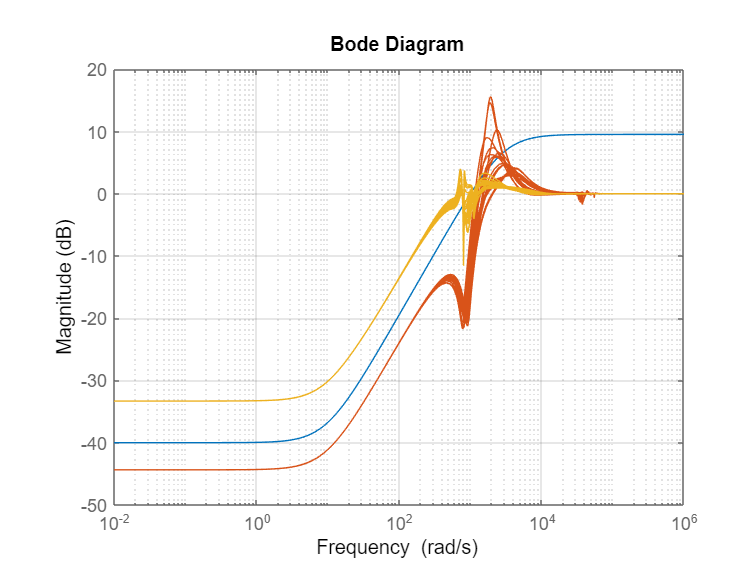

G = [VCM PZT];
bodemag(1/Wp,1-feedback(G*K,1),1-feedback(G*Kmu,1))

The $\mu
$-synthesis design has worse performance overall, but has much better robust stability with the actual plant than does the $H_\infty$ design.  

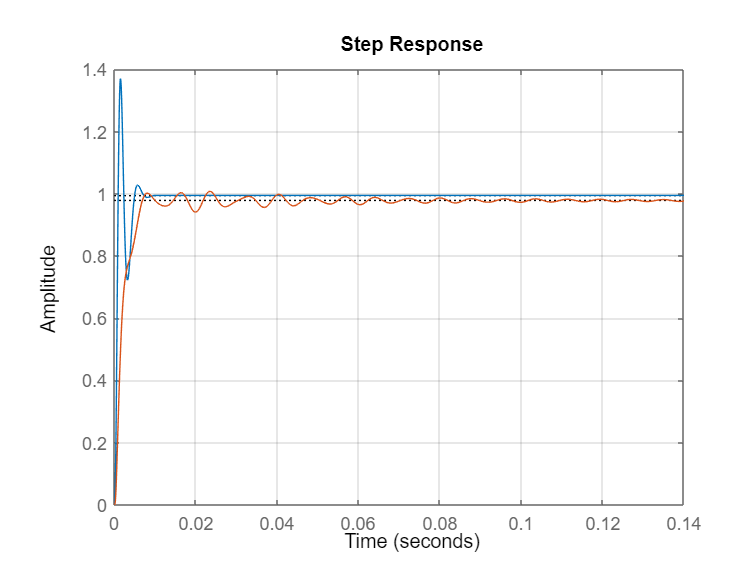

step(feedback([Gv Gp]*K,1),feedback([Gv Gp]*Kmu,1))

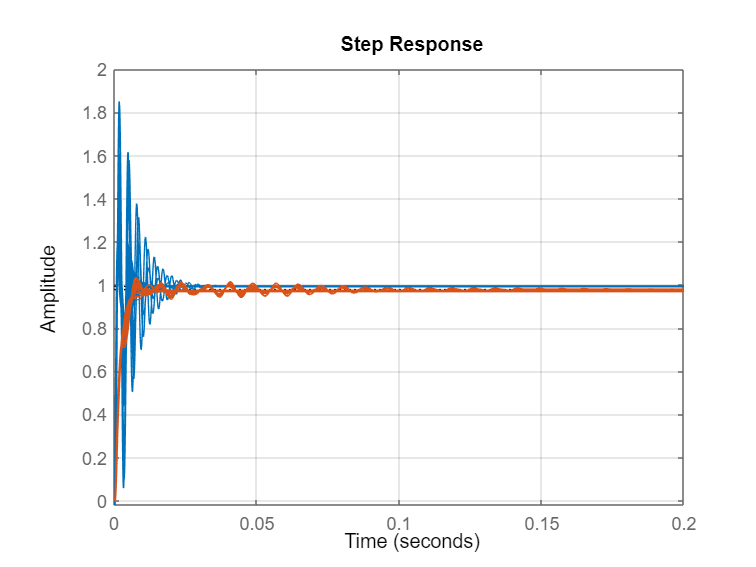

step(feedback(G*K,1),feedback(G*Kmu,1))

For the nominal model I like the $H_\infty$ response better; however, things change with uncertainty.  The responses with $\mu$ show much less variability than those designed with $H_\infty$.  Even for this simple system with almost the simplest uncertainty model, it is clear that D-K iteration can make a big difference and produce designs with better robust stability and performance properties.